clear; clc; close all;

**OFDM Parameters**

nfft = 1024;                    % nfft size equal to number of subcarriers
BW = 1000000000;                % Bandwidth of subcarriers (-F/2 F/2)
M = 4;                          % Baseband modulation order
cp_len = nfft/4;                % Cyclic Prefix length
ofdm_symbols =  1;               % Number of ofdm symbols to transmit
ebno_test = -5:2:30;
symbol_plot = 10;
rep = 4;                        % Repetition of pilots
pilot_index = [112:rep:913];    % Insert a pilot every 5 data sub-carriers
pilot_val = -0.7072+0.7072i;    % Set value of pilot subcarriers
data_index = 1:nfft;            % Index of data subcarriers
cw_tone = 10000000;
% Set 224 zero padded subcarriers: 111 on lower and upper subcarriers
% and 2 on each side of carrier
zp_index = [1:111,914:1024];
multipath = [0 1 0.02 0.8];            % Multipath taps
no_multi = [1 0 0 0];
%multipath = [1 0.3 0.5 0];
data_index([zp_index,pilot_index]) = [];
scs = BW/nfft;
plot_v = 0;
num_data_bits = length(data_index)*ofdm_symbols

num_data_bits = 601

**Modulate:**

[ofdm_signal,reference_pilot,mod_data,t,t2]=ofdm_transmit(nfft,BW,M,cp_len, ...
    ofdm_symbols,zp_index,pilot_index,0);
cw_signal = cos(2*pi*cw_tone*t2)'+i*sin(2*pi*cw_tone*t2)';

**Scale:**

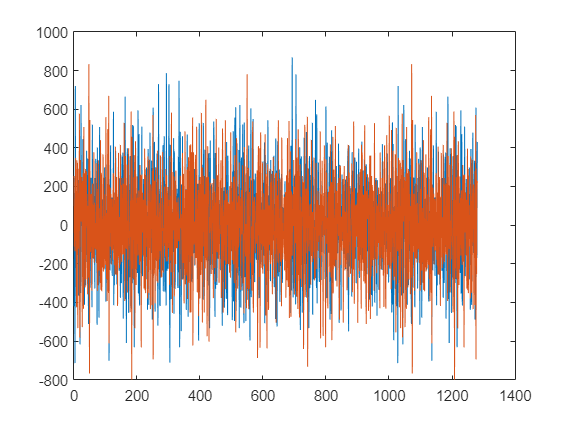

file = fopen('../../HW/modules/sim/equalizer_input_samples.txt','wt');
ofdm_scaled_signal = round(10000*ofdm_signal);
for i = 1:length(ofdm_signal)
    if i == length(ofdm_signal)
        fprintf(file,"%d, ",int16(real(ofdm_scaled_signal(i))));
        fprintf(file,"%d",int16(imag(ofdm_scaled_signal(i))));
    else
        fprintf(file,"%d, ",int16(real(ofdm_scaled_signal(i))));
        fprintf(file,"%d\n",int16(imag(ofdm_scaled_signal(i))));
    end
end

file = fopen('../../HW/modules/sim/cw_input_samples.txt','wt');
cw_scaled_signal = round(10000*cw_signal);
for i = 1:length(cw_signal)
    if i == length(cw_signal)
        fprintf(file,"%d, ",int16(real(cw_scaled_signal(i))));
        fprintf(file,"%d",int16(imag(cw_scaled_signal(i))));
    else
        fprintf(file,"%d, ",int16(real(cw_scaled_signal(i))));
        fprintf(file,"%d\n",int16(imag(cw_scaled_signal(i))));
    end
end
figure(),plot(real(ofdm_scaled_signal)),hold on,plot(imag(ofdm_scaled_signal))

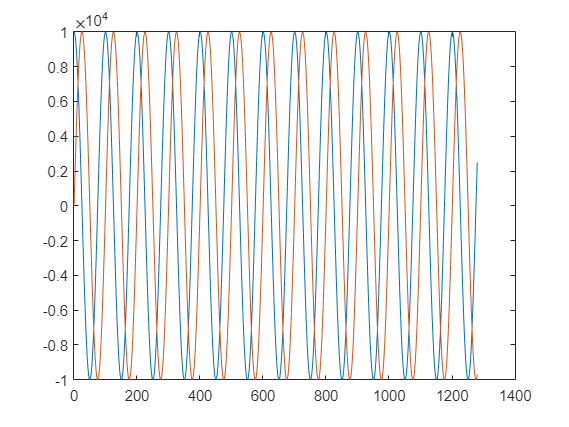

figure,plot(real(cw_scaled_signal)),hold on,plot(imag(cw_scaled_signal))